# Taller X

### 23/05/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 8 y 9*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de integración*

*Los métodos de integración son muy variados, por lo cual, los métodos con los que contamos nos pueden quedar cortos para las necesidades que tenemos y sea necesario un nuevo método para la resolución de ejercicios.*

`        [quad, raices, nodos, coefs] = GaussLegendre( f, a, b, N), `*Cuadratura de Gauss-Legendre*

`            - f funcion integrando creada con @`

`            - a y b limites superior e inferior de integracion`

`            - N es el numero de nodos en la cuadratura`

`            - quad es el valor de cuadratura`

`            - raices es el vector de raices del polinomio de Legendre N`

`            - nodos es el vector de nodos de la cuadratura en [a,b]`

`            - coefs es el vector de pesos de la cuadratura`

`        El error para este metodo se calcula como se indica:`

            `- Aquí el error toma la forma diferencial:`

`        ((b - a)/ 2)^(2*N + 1) * ( 2^(N + 1) * factorial(N)^4 ) / ((2*N +1) * factorial(2*N)^3)* max{f^(2*N)(x)}`

            `- El error tiene orden O( ((b - a)/(N - 1)) ), con exponente N + 1 con N par y N + 2 con N impar, N es el número de puntos. En las clases se explica con M tal de que M + 1 es el número de puntos, así las formulas quedarían M + 2, y M + 3 respectivamente.`

***Reglas abiertas:***

*No contamos con métodos de integraciones abiertas especificamente, por lo cual si se busca implementar el método, es necesario definir.*

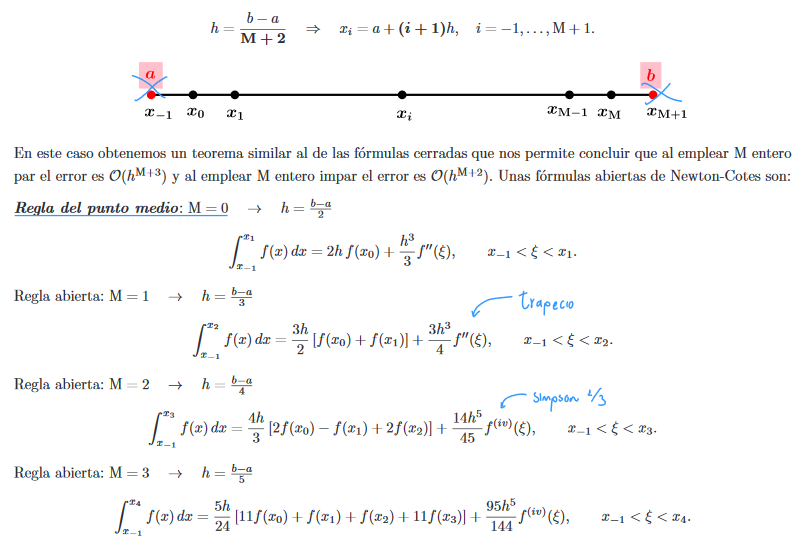

***Reglas cerradas:***

*Contamos con algunos métodos de integración cerrada, pero igualmente, de ser necesario, algunos otros necesitan ser creados, de igual forma estos métodos cuentan con una forma simple, la cual toma el mínimo número de intervalos posibles para efectuar el método.*

`        s = simprl (f, a, b, M)`*, Método de Simpson*

`            - f funcion integrando creada con @`

`            - a y b son los limites superior e inferior de integracion`

`            - M es el numero de subintervalos`

`            - s es la suma de la regla de simpson`

`        El error para este metodo se calcula como se indica:`

            `- Condición simple: ``- h^5 / 90 * max{f^(iv)(x)} : h = (b - a)/2`

            `- Condición compuesta:`` - h^4 / 180 *(b - a) *max{f^(iv)(x)} : h = (b - a)/M`

`        s =  traprl(f, a, b, M)`*, Método de trapecios*

`            - f funcion integrando creada con @`

`            - a y b son los limites superior e inferior de integracion`

`            - M es el numero de subintervalos`

`            - s es la suma de la regla trapezoidal (integral)`

`        El error para este metodo se calcula como se indica:`

            `- Condición simple: - ``h^3 / 12 * max{f''(x)} : h = (b - a)/2`

            `- Condición compuesta:`` - h^2 / 12 *(b - a) *max{f''(x)} : h = (b - a)/M`

*        >>Durante los talleres se agrega el método de punto medio, con el cual el error se halla como:*

`        s = midpntrl (f, a, b, M)`*, Método de punto medio*

`            - f funcion integrando creada con @`

`            - a y b son los limites superior e inferior de integracion`

`            - M es el numero de subintervalos`

`            - s es la suma de la regla de punto medio`

`        El error para este metodo se calcula como se indica:`

            `- Condición simple: ``h^3 / 3 * max{f''(x)} : h = (b - a)/2`

            `- Condición compuesta:`` (b - a) / 6 *h.^2 *max{f''(x)} : h = (b - a)/(M + 2)`

#### *        Métodos de resolución de ecuaciones diferenciales u***nivariable**   

`        E = euler (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - E = [T', Y'] donde T es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        T4 = taylor (df, a, b, ya, M) `*Método de Taylor de Orden 4.*

`            - df = [y', y'', y''', y''''] funcion creada con @ donde  y' = f(t, y)`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - T4 = [T', Y'] donde  T  es el vector de abscisas y`

`                Y  es el vector de ordenadas`

`        H = heun (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - H = [T', Y'] donde  T  es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        EM = eulerMod (f, a, b, ya, M)`

`            - f funcion creada con @`

`            - a y b son los extremos izquierdo y derecho`

`            - ya es la condicion inicial  y(a)`

`            - M es el numero de pasos`

`            - EM = [T', Y'] donde  T  es el vector de abscisas y`

`                Y es el vector de ordenadas`

`        R = rk4 (f, a, b, ya, M)`

                        `- f funcion creada con @`

                        `- a y b son los extremos izquierdo y derecho`

                        `- ya es la condicion inicial  y(a)`

                        `- M es el numero de pasos`

                        `- R = [T', Y'] donde  T  es el vector de abscisas`

                        `    y  Y  es el vector de ordenadas`

### Solución númerica de ecuaciones diferenciales ordinarias

Para el taller de esta semana se solucionan dos ejercicios: $\left.\left.\left.4\right),5\right)\;c,\;\&\;12\right)$

**4) **Utilizamos el método de Taylor orden 4 para solucionar las ecuaciones diferenciales, y verificamos usando el método `ode45.m `propio de matlab para verificar:


$$\begin{array}{l}
y^{\prime } =\frac{y}{t}-{\left(\frac{y}{t}\right)}^2 ,\;\;1\le t\le 2,\;y\left(1\right)=1,\;h=0\ldotp 1\\
y^* \left(t\right)=\frac{t}{1+\ln \left(t\right)}
\end{array}$$


help taylor
clear
syms f(t, y)

f(t, y) = y/t - (y/t)^2; % Función = y'
df(t, y) = diff(f, t) + f(t, y) * diff(f, y); % Derivada = y''
d2f(t, y) = diff(df,t) + df(t, y) * diff(df, y); % y'''
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y); % y''''

  Entrada  - df = [y', y'', y''', y''''] funcion creada con @
             donde  y' = f(t, y)
           - a y b son los extremos izquierdo y derecho
           - ya es la condicion inicial  y(a)
           - M es el numero de pasos
  Salida   - T4 = [T', Y'] donde  T  es el vector de abscisas y
             Y  es el vector de ordenadas

    Other functions named taylor




df(t, y) = [f, df, d2f, d3f];

df = matlabFunction(df);
a = 1; b = 2; ya = 1; M = (b - a)/.1;

T4 = taylor(df, a, b, ya, M);

clf('reset')
hold on
fplot(@(t) t ./ (1 + log(t)), [1 2])
plot(T4(:, 1), T4(:, 2), '.r')
legend('Function', 'Aprox Taylor T2', 'location', "best")
grid on
hold off


$$\begin{array}{l}
y^{\prime } =-\;\left(y+1\right)\;\left(y+3\right),\;\;0\le t\le 2,\;\;\;y\left(0\right)=-2,\;\;h\;=0\ldotp 2\\
y^* \left(t\right)=-3+\frac{2}{1+e^{-2\;t} }
\end{array}$$


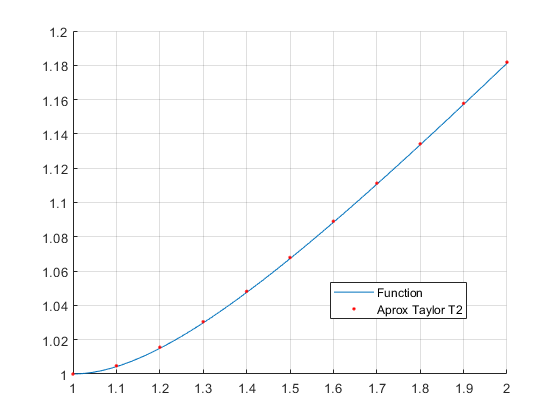

clear
syms f(t, y)

f(t, y) = -(y + 1)*(y + 3);
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);
d2f(t, y) = diff(df, t) + df(t, y) * diff(df, y);
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);


df2(t, y) = [f, df, 0, 0]; % Taylor 2
df2 = matlabFunction(df2);

df4(t, y) = [f, df, d2f, d3f]; % Taylor 4
df4 = matlabFunction(df4);

a = 0; b = 2; ya = -2; M = (b - a)/.2; % Parametros de los métodos

T4 = taylor(df4, a, b, ya, M);

T2 = taylor(df2, a, b, ya, M); 
T2(T2 == 1.8, :) % Solicitamos valor de y(t = 1.8) -> [t, y(t)]
T2(6,:) % Solicitamos valor de T4_5 -> T4(6)
clf('reset')
hold on
fplot(@(t) -3 + 2 ./ (1 + exp(-2.*t)), [a b])
plot(T2(:, 1), T2(:, 2), '.', 'DisplayName', 'Aprx. Taylor 2')
plot(T4(:, 1), T4(:, 2), '.', 'DisplayName', 'Aprx. Taylor 4')
legend('Location',"best")
grid on
hold off

ans =     1.8000   -1.0545


**5) **Utilice el método de Taylor de orden 2 y orden 4 para resolver el problema de valor inicial:


$$\begin{array}{l}
y^{\prime } =\;1\;+y^2 \;\;\\
0\le t\le 1,\;y\left(0\right)=0,\;h=0\ldotp 01
\end{array}$$


clear

ans =     1.0000   -1.2363


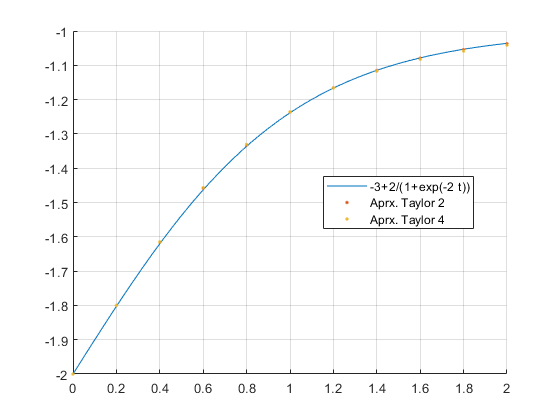

syms f(t, y)

f(t, y) = 1 + y^2;
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);
d2f(t, y) = diff(df, t) + df(t, y) * diff(df, y);
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);

df2(t, y) = [f, df, 0, 0]; % Taylor 2

df2 = matlabFunction(df2);

df4(t, y) = [f, df, d2f, d3f]; % Taylor 4
df4 = matlabFunction(df4);

a = 0; b = 1; ya = 0; M = (b - a)/.01; % Parametros

T2 = taylor(df2, a, b, ya, M);
T4 = taylor(df4, a, b, ya, M);
T4Before = T4; % Gurdamos

clf('reset')
hold on
plot(T2(:, 1), T2(:, 2), 'DisplayName', 'Aprx. Taylor 2')
plot(T4(:, 1), T4(:, 2), 'DisplayName', 'Aprx. Taylor 4')
legend('Location',"best")
grid on
hold off

Veamos que sucede al alterar la condición inicial $y\left(0\right)=-1$:

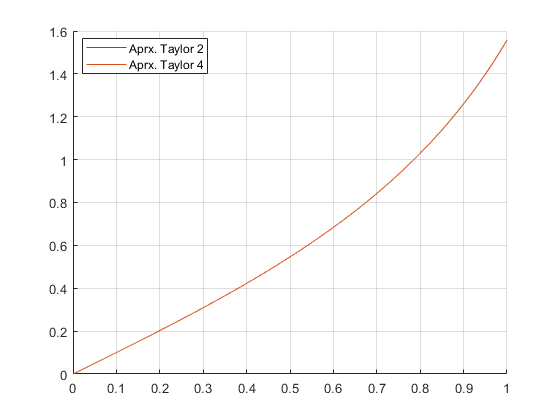

clear f df2 df4
f(t, y) = 1 + y^2;
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);
d2f(t, y) = diff(df, t) + df(t, y) * diff(df, y);
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);

df2(t, y) = [f, df, 0, 0]; % Taylor 2
df2 = matlabFunction(df2);

df4(t, y) = [f, df, d2f, d3f]; % Taylor 4
df4 = matlabFunction(df4);


a = 0; b = 1; ya = -1; M = (b - a)/.01; % Parametros

T2 = taylor(df2, a, b, ya, M);
T4 = taylor(df4, a, b, ya, M); % Nueva aproximación

clf('reset')
hold on
plot(T4(:, 1), T4(:, 2), 'DisplayName', 'Taylor 4 y(0) = 1')
plot(T4Before(:, 1), T4Before(:, 2), 'DisplayName', 'Taylor 4 y(0) = -1')
legend('Location',"best")
grid on
hold off

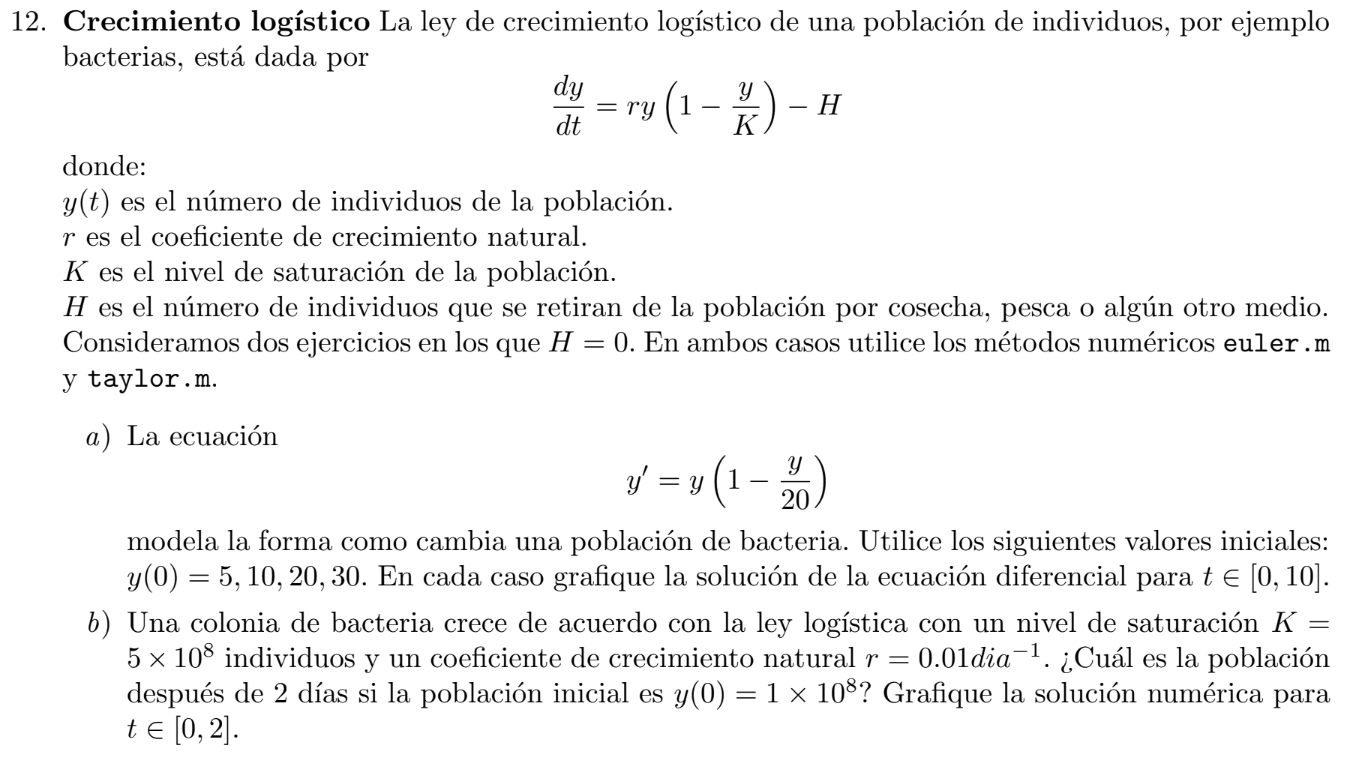

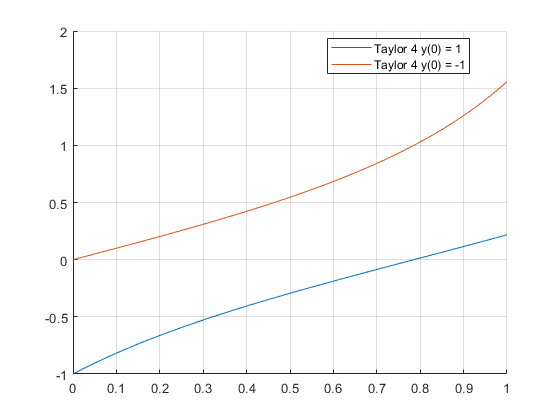

clear
syms f(t, y)

H = 0; K = 5E8; r = .01;

% Definimos las derivadas de y
f(t, y) = r * y * (1 - y / K) - H;
df(t, y) = diff(f, t) + f(t, y) * diff(f, y);
d2f(t, y) = diff(df, t) + df(t, y) * diff(df, y);
d3f(t, y) = diff(d2f, t) + d2f(t, y) * diff(d2f, y);

% Generamos el vector

df(t, y) = [f, df, d2f, d3f];

% Convertimos a funciones de Matlab
f = matlabFunction(f);
df = matlabFunction(df);

a = 0; b = 2; ya = 1E8; M = 100;

E = euler(f, a, b, ya, M);

$$f(t, y) = -\frac{y\,\left(\frac{y}{500000000}-1\right)}{100}$$

T4 = taylor(df, a, b, ya, M);

clf('reset')
hold on
plot(T4(:, 1), T4(:, 2), 'DisplayName', 'Aprx. Taylor')
plot(E(:, 1), E(:, 2), 'DisplayName', 'Aprx. Euler')
legend('Location', "best")
grid on
hold off

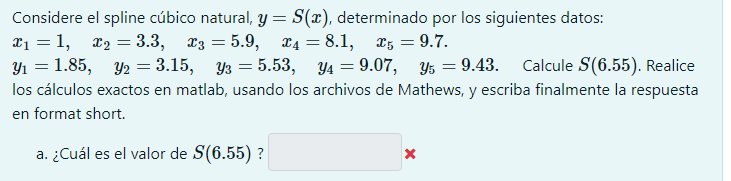

clear

X = [1 3.3 5.9 8.1 9.7];
Y = [1.85 3.15 5.53 9.07 9.43];

CN = csnatural(X, Y)
coef = CN(3,:);
S3 = @(x) polyval(coef, x - X(3));
S3(6.55)
% S = @(x) piecewise() ... Función por partes
GraficaCercha(X, Y, CN)
xline(6.5)
yline(S3(6.5))

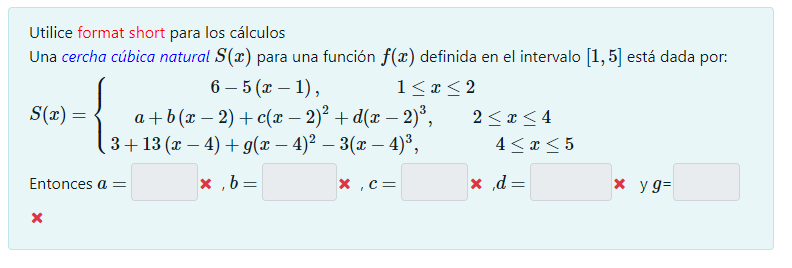

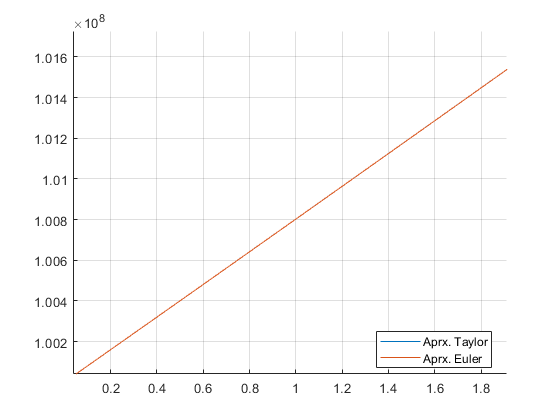

clear

syms S(x) a b c d g

% Spline
S1(x) = 6 - 5*(x - 1);
S2(x) = a + b*(x - 2) + c*(x - 2)^2 + d*(x - 2)^3;
S3(x) = 3 + 13*(x - 4) + g*(x - 4)^2 - 3*(x - 4)^3;

% Derivada

CN =     0.0016         0    0.5569    1.8500
    0.0452    0.0109    0.5819    3.1500
   -0.1537    0.3631    1.5542    5.5300
    0.1357   -0.6515    0.9199    9.0700


dS1(x) = diff(S1);
dS2(x) = diff(S2);
dS3(x) = diff(S3);

ans = 6.6515

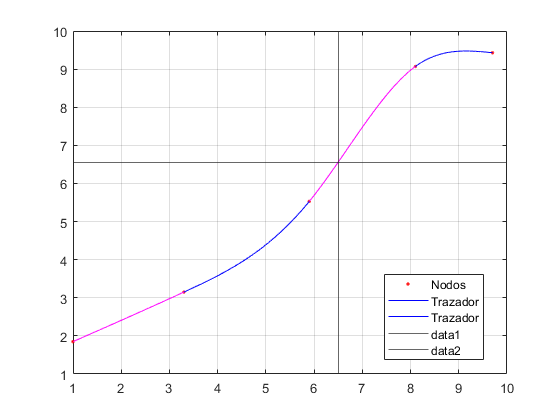


% Curvatura
d2S1(x) = diff(dS1);
d2S2(x) = diff(dS2);

d2S3(x) = diff(dS3);

% Cond. Continuidad
Eq1 = S1(2) == S2(2), Eq2 = S2(4) == S3(4)
% Cond. Diferenciabilidad
Eq3 = dS1(2) == dS2(2), Eq4 = dS2(4) == dS3(4)
% Cond. Curvatura
Eq5 = d2S1(2) == d2S2(2), Eq6 = d2S2(4) == d2S3(4)
% Cond. Naturalidad
Eq7 = d2S1(1) == 0, Eq8 = d2S3(5) == 0
simplify(Eq6,'Steps',0)
S = solve(Eq1, Eq2, Eq3, Eq4, Eq5, Eq6, Eq7, Eq8)
a = S.a, b = S.b, c = S.c, d = S.d, g = S.g % Constantes, para que S(x) sea un Spline Natural
S = piecewise((1 <= x) & (x <= 2), S1, (2 <= x) & (x <= 4), S2, (4 <= x) & (x <= 5), S3)
S(2)
Eq1 = limit(S(x), x, 2, 'left') == limit(S(x), x, 2, 'right')

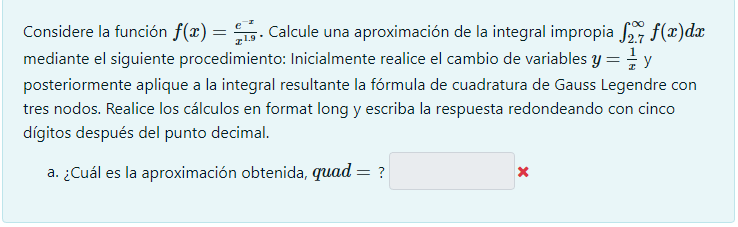


$$\begin{array}{l}
f\left(x\right)=\frac{e^{-x} }{x^{1\ldotp 9} }\;\to \;\;g\left(x\right)=f\left(\frac{1}{x}\right)\\
y=\frac{1}{x}\;\;\to \;\;\textrm{dy}=-\frac{1}{x^2 }\;\textrm{dx}
\end{array}$$


clear
format long
syms f(x)

f(x) = exp(-x) / x ^ 1.9;
g(x) = f(1/x) * - 1 / x ^ 2; % Cambio de variable

$$Eq1 = 1=a$$

$$Eq2 = a+2\,b+4\,c+8\,d=3$$


f = matlabFunction(f);

$$Eq3 = -5=b$$

$$Eq4 = b+4\,c+12\,d=13$$

g = matlabFunction(g);


$$Eq5 = 0=2\,c$$

$$Eq6 = 2\,c+12\,d=2\,g$$

I = GaussLegendre(g, 1/2.7, 0, 3) % Ojo con los limites
I = integral(f, 2.7, inf)

$$Eq7 = 0=0$$

$$Eq8 = 2\,g-18=0$$

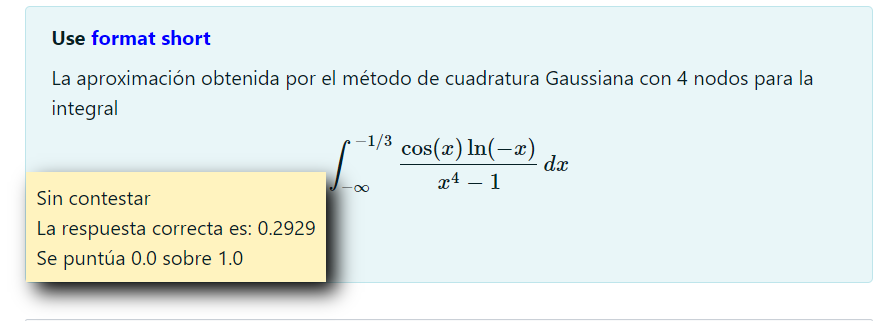


$$\begin{array}{l}
f\left(x\right)=\frac{\cos \left(x\right)\;\log \left(-x\right)}{x^4 -1}\;\to \;g\left(x\right)=\frac{\cos \left(\frac{1}{x}\right)\;\log \left(-\frac{1}{x}\right)}{{\left(\frac{1}{x}\right)}^4 -1}=f\left(\frac{1}{x}\right)\\
t=\frac{1}{x}\;\to \textrm{dx}=-\frac{1}{t^2 }\;\textrm{dt}\\
\int \frac{\cos \left(x\right)\;\log \left(-x\right)}{x^4 -1}\;\textrm{dx}\;\to \;\;\int \frac{\cos \left(\frac{1}{t}\right)\;\log \left(-\frac{1}{t}\right)}{{\left(\frac{1}{t}\right)}^4 -1}\;-\frac{1}{t^2 }\textrm{dt}\;=\int f\left(\frac{1}{x}\right)\ldotp -\frac{1}{x^2 }\textrm{dx}
\end{array}$$


clear

$$ans = 2\,c+12\,d=2\,g$$

syms f(x)

S = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]
    d: [1×1 sym]
    g: [1×1 sym]


$$a = 1$$

$$b = -5$$

$$c = 0$$

$$d = \frac{3}{2}$$

$$g = 9$$

f(x) = - real(log(-x + 2)) / (x * (x - 2)) % -inf -> 1

$$S(x) = \left\{ \begin{array}{cl} 11-5\,x & \text{ if }x\in \left[1,2\right]\\ a+b\,\left(x-2\right)+c\,{\left(x-2\right)}^{2}+d\,{\left(x-2\right)}^{3} & \text{ if }x\in \left[2,4\right]\\ 13\,x-3\,{\left(x-4\right)}^{3}+g\,{\left(x-4\right)}^{2}-49 & \text{ if }x\in \left[4,5\right] \end{array}\right.$$

g(x) = f(1/x) * -1/x^2;

$$ans = 1$$

g = matlabFunction(g);

$$Eq1 = 1=a$$

f = matlabFunction(f);

I1 = GaussLegendre(g, 0, -1, 5) % Integral de -inf -> -1
I2 = GaussLegendre(f, -1, 0, 5) % integral de -1 -> 0
I3 = GaussLegendre(f, 0, 1, 5)
I = I1 + I2 + I3

clear
f = @(x) exp(-x) ./ x.^(1.9)
g = @(x) f(1./x) .* -1./x.^2
I = GaussLegendre(g, 1/2.7, 0, 3)

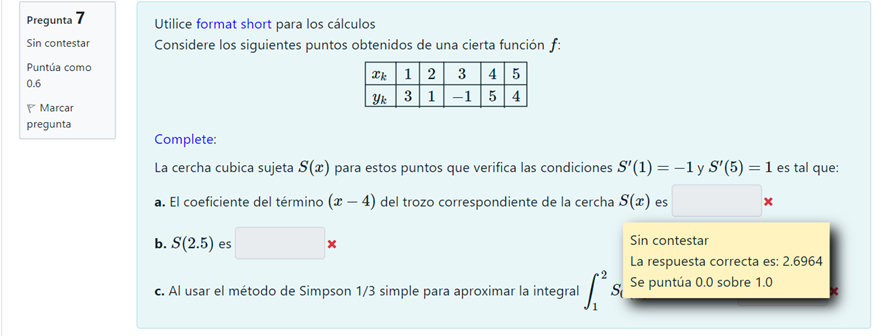

clear
format short


I =    0.006364438646992


X = 1:5

I =    0.006434383745312


Y = [3 1 -1 5 4];

C = csfit(X, Y, -1, 1)
C(3, 3 -1 + 1) % Termino de (x - 3)
S2 = @(x) polyval(C(2,:), x - X(2));
S2(2.5)
S1 = @(x) polyval(C(1,:), x - X(1));

$$f(x) = -\frac{\log\left(\left|x-2\right|\right)}{x\,\left(x-2\right)}$$


I = simprl(S1, 1, 2, 2)

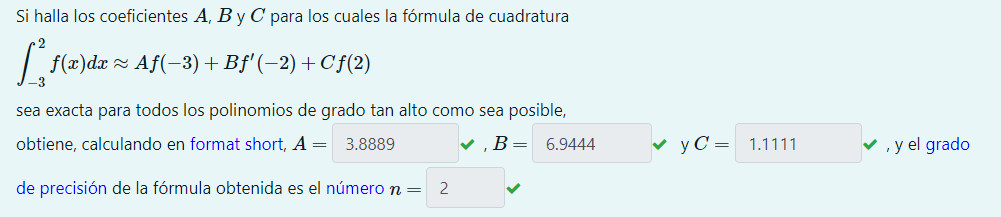


$$\int a_0 +a_1 x+\ldotp \ldotp \ldotp \textrm{dx}=a_0 \int 1\textrm{dx}+a_1 \;\int x\;\textrm{dx}+\ldotp \ldotp \ldotp$$


clear
syms f(x) A B C


I1 = -0.9985

% Verificamos Grado 0;

I2 = -1.6253

f(x) = x^0

I3 = 1.4117

df(x) = diff(f)

I = -1.2121

I = int(f, -3, 2);

Eq1 = I == A*f(-3) + B*df(-2) + C*f(2)

f = function_handle with value:
    @(x)exp(-x)./x.^(1.9)


% Grado 1:

g = function_handle with value:
    @(x)f(1./x).*-1./x.^2


f(x) = x;

I =    0.006364438646992


df(x) = diff(f);
I = int(f, -3, 2);

Eq2 = I == A*f(-3) + B*df(-2) + C*f(2)
% Grado 2:
f(x) = x^2;

X =      1     2     3     4     5


df(x) = diff(f);
I = int(f, -3, 2);


C =    -0.5536   -0.4464   -1.0000    3.0000
    3.6607   -2.1071   -3.5536    1.0000
   -6.0893    8.8750    3.2143   -1.0000
    5.6964   -9.3929    2.6964    5.0000


Eq3 = I == A*f(-3) + B*df(-2) + C*f(2)

ans = 3.2143

% Grado 3:
f(x) = x^3;

ans = -0.8460

df(x) = diff(f);
I = int(f, -3, 2);


I = 2.2128

Eq4 = I == A*f(-3) + B*df(-2) + C*f(2)
S = solve(Eq1, Eq2, Eq3) % Grado de precisión es de n = 2
S.A, S.B, S.C
S = solve(Eq1, Eq2, Eq3, Eq4)

clear
syms f(x)
f(x) = (-log(x+2))./(x.*(x+2))
g(x) = f(1/x) * 1/x^2  

$$f(x) = 1$$

g = matlabFunction(g);

$$df(x) = 0$$

f =  matlabFunction(f);

I = GaussLegendre(f,-1,0,4) + GaussLegendre(f,0,1,4) + ...

$$Eq1 = 5=A+C$$

    GaussLegendre(g, 0, 1, 4)

%Pregunta 10
clear
syms f(t,p) b d k

b = 0.091 ; k = 1.4e-6;

$$Eq2 = -\frac{5}{2}=B-3\,A+2\,C$$

f(t,p) = b * p - k * p * p
%ya = P0
f = matlabFunction(f);
EM = eulerMod(f,0,5,67,5/0.05)
EM(end,:)

clear

$$Eq3 = \frac{35}{3}=9\,A-4\,B+4\,C$$

syms f(t, y)

f(t, y) = (t - 3)*exp(-t)*sin(y) + 1;
df(t, y) = diff(f, y)
fplot(abs(df(t, 0)), [2 4])
yline(.1)

$$Eq4 = -\frac{65}{4}=12\,B-27\,A+8\,C$$

yline(.14)

S = struct with fields:
    A: [1×1 sym]
    B: [1×1 sym]
    C: [1×1 sym]


yline(.2)

$$ans = \frac{35}{9}$$

$$ans = \frac{125}{18}$$

$$ans = \frac{10}{9}$$

yline(.18)

S = struct with fields:
    A: [0×1 sym]
    B: [0×1 sym]
    C: [0×1 sym]


grid on

clear
syms S(x) a b c d g
%spline

$$f(x) = -\frac{\log\left(x+2\right)}{x\,\left(x+2\right)}$$

S1(x)=6-5*(x-1);

$$g(x) = -\frac{\log\left(\frac{1}{x}+2\right)}{x\,\left(\frac{1}{x}+2\right)}$$

S2(x)=a+b*(x-3)+c*(x-3)^2+d*(x-3)^3;
S3(x)=3+31*(x-4)+g*(x-4)^2-12*(x-4)^3;
%derivada
dS1(x)=diff(S1);
dS2(x)=diff(S2);

I = -1.2007

dS3(x)=diff(S3);
%curvatura
d2S1(x)=diff(dS1);
d2S2(x)=diff(dS2);
d2S3(x)=diff(dS3);
%Cond. Continuidad
Eq1=S1(3)==S2(3), Eq2=S2(4)==S3(4)

$$f(t, p) = \frac{91\,p}{1000}-\frac{6611313076017503\,p^{2}}{4722366482869645213696}$$

%Cond. Diferenciabilidad
Eq3=dS1(3)==dS2(3), Eq4=dS2(4)==dS3(4)
%Cond. curvatura

EM =          0   67.0000
    0.0500   67.3052
    0.1000   67.6118
    0.1500   67.9199
    0.2000   68.2293
    0.2500   68.5401
    0.3000   68.8523
    0.3500   69.1660
    0.4000   69.4811
    0.4500   69.7976


Eq5=d2S1(3)==d2S2(3), Eq6=d2S2(4)==d2S3(4)

ans =     5.0000  105.5408


S= solve(Eq1, Eq2, Eq3, Eq4, Eq5, Eq6)
a=S.a, b=S.b, c=S.c, d=S.d, g=S.g

clear
syms f(x)

f(x) = real(-log(-x + 2) / (x * (x - 2)))

$$df(t, y) = {\mathrm{e}}^{-t}\,\cos\left(y\right)\,\left(t-3\right)$$

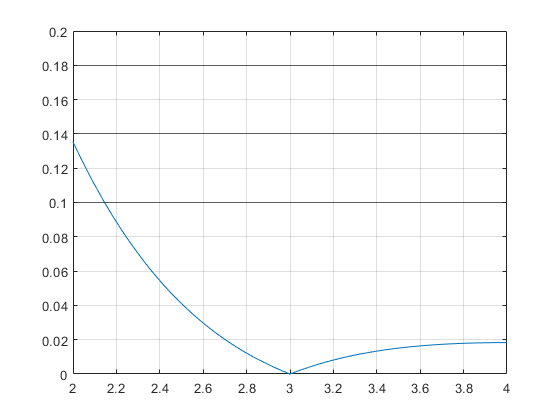

$$Eq1 = -4=a$$

$$Eq2 = a+b+c+d=3$$

$$Eq3 = -5=b$$

$$Eq4 = b+2\,c+3\,d=31$$

$$Eq5 = 0=2\,c$$

$$Eq6 = 2\,c+6\,d=2\,g$$

S = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]
    d: [1×1 sym]
    g: [1×1 sym]


$$a = -4$$

$$b = -5$$

$$c = 0$$

$$d = 12$$

$$g = 36$$

$$f(x) = -\mathrm{real}\left(\frac{\log\left(2-x\right)}{x\,\left(x-2\right)}\right)$$

$$g(x) = \frac{\mathrm{real}\left(\frac{x\,\log\left(2-\frac{1}{x}\right)}{\frac{1}{x}-2}\right)}{x^{2}}$$

I = -Inf

g(x) = f(1/x) * -1/x^2

g = matlabFunction(g);

I = GaussLegendre(g, 0, 1, 5)